[y_noise, Fs_noise] = audioread("sound_sample\noise.wav");
[y_music, Fs_music] = audioread("sound_sample\music_sample.wav");

%refine data
y_remusic = y_music*0.4;
y_renoise = y_noise(1:length(y_music),:);

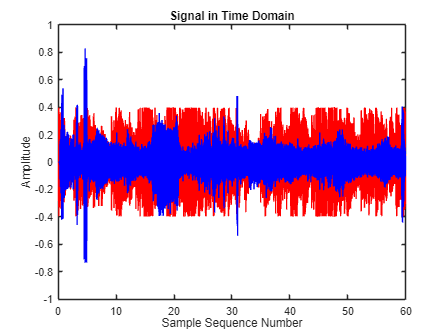

% Plot informations

% Mix tape
y_mixture = y_remusic + y_renoise;

plot_numberOfSampler = linspace(0,length(y_music)/Fs_music, length(y_remusic));
figure;
plot(plot_numberOfSampler, y_remusic,Color="r");
hold on;
plot(plot_numberOfSampler, y_renoise, Color="b");
title('Signal in Time Domain')
xlabel('Sample Sequence Number')
ylabel('Amplitude')
ylim([-1,1])
hold off;

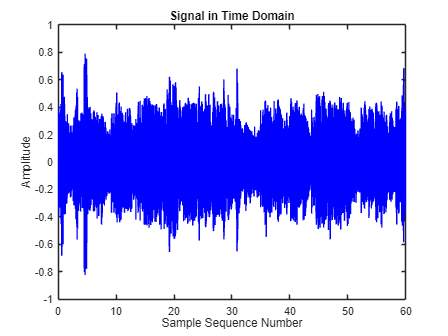

figure;
plot(plot_numberOfSampler, y_mixture, color="b");
title('Signal in Time Domain')
xlabel('Sample Sequence Number')
ylabel('Amplitude')
ylim([-1,1])
hold off;

% Audio player
%the_audioPlayer = audioplayer(y_mixture, Fs_music)
sound(y_mixture, Fs_music)
%play(the_audioPlayer)